## **CT - scan project.**

Robin Nillson  --  Halldór Stefán Laxdal.

addpath('.\functions')

load('CTdata.mat')
2*floor(size(g,1)/(2*sqrt(2)))

ans = 100

*"Type load('data.mat') to load a number of sinogram. The first exercise uses sinogram g. The size can be found with size(g) in MATLAB. The output should be 144 180, which shows that the size of the array (sinogram) is 144 rows ´ 180 columns. The sinogram was formed based on multiple parallel beam (*$-71\le l\le 72$* ) projections of an object from 180 different directions: 0 to 179 degrees with a step size of 1 degree."*

### PART A: Back projection

*"A1: Write down the expression for reconstruction using back-projection and explain the meaning of each term in the equation."*

$b_{\theta \;} \left(x,y\right)=g\left(\textrm{xcos}\theta +\textrm{ysin}\;\theta \;,\theta \;\right)\;$where $g\left(\cdot ,\cdot \;\right)\;$is the sinogram image and $\theta$ is angle of which the CT-scanner was rotated comared to the body:

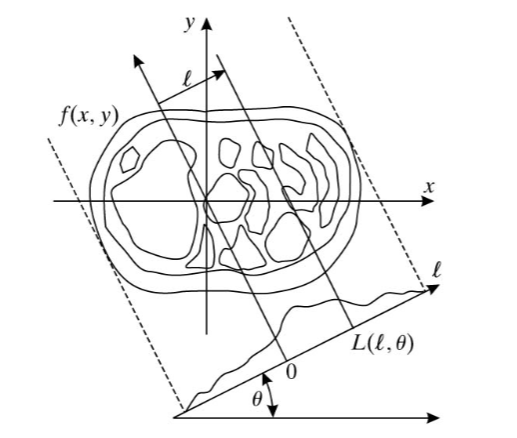

where $L\left(l,\theta \right)$is a line in the plane and $f\left(x,y\right)$ is the body. 

*"A2. Compute and plot the image from the back projection of the sinogram data at *$\theta ={30}^o$*."*

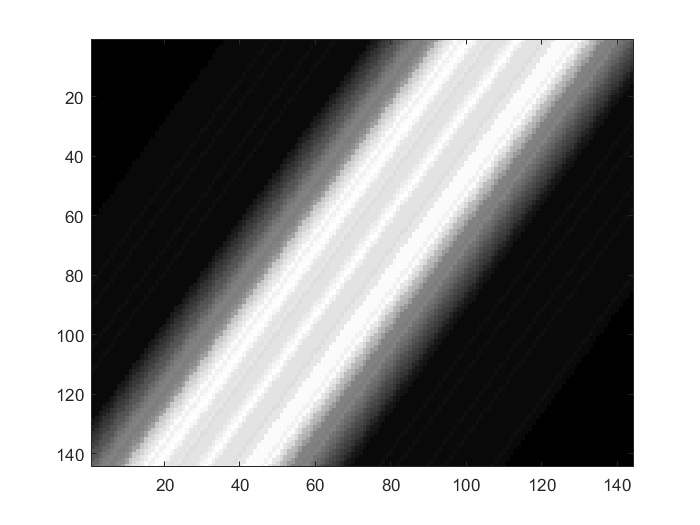

theta = 30;
back_proj = back_projection(g, theta, 30);
imagesc(back_proj); colormap gray

*"A3. Compute and plot the back projection summation image, with N= 6, 12, 30, 60 and 180, where N is the number of back projections. Multiply the resultant image by the factor of *$\frac{\pi \;}{2N}$*where N is the number of projections. Compare and comment on the results based on different values of N."*

N = 6

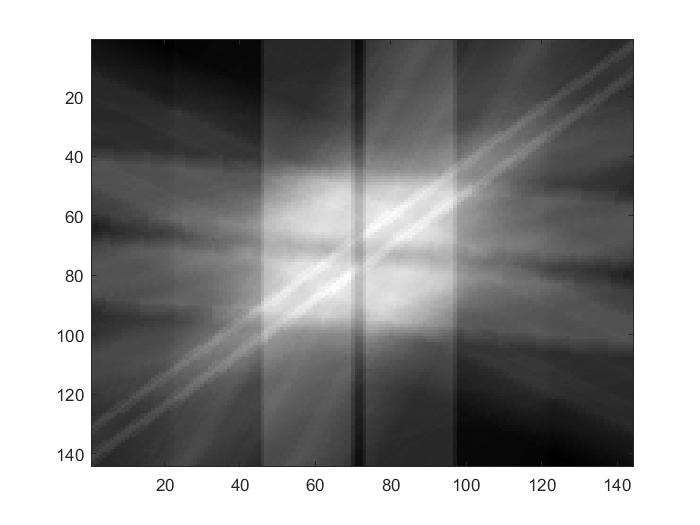

N = 12

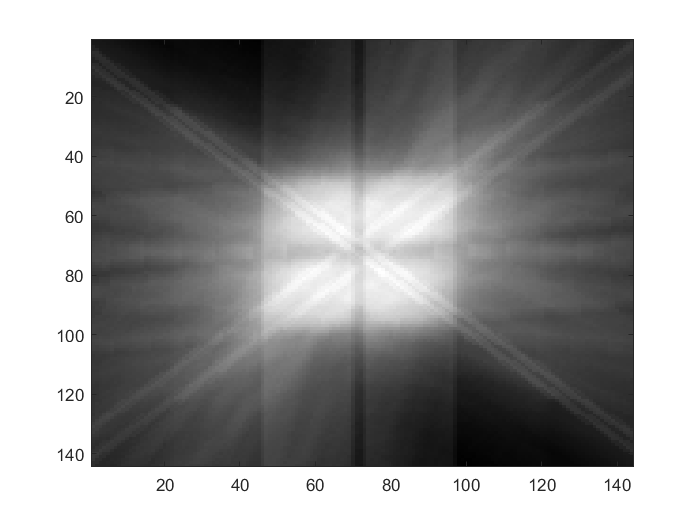

N = 30

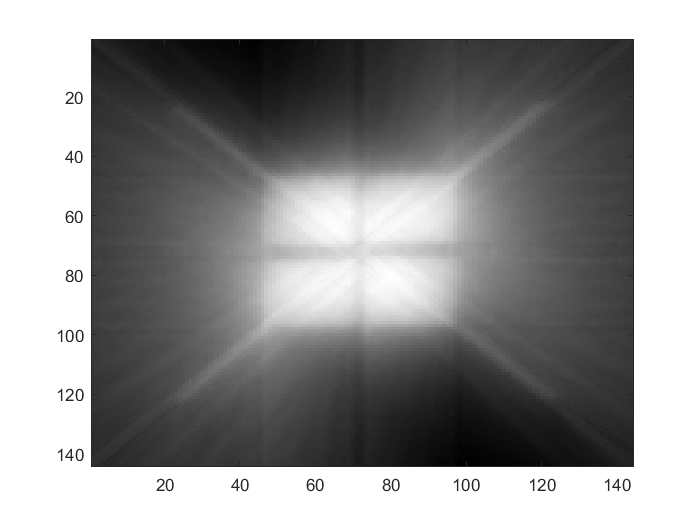

N = 60

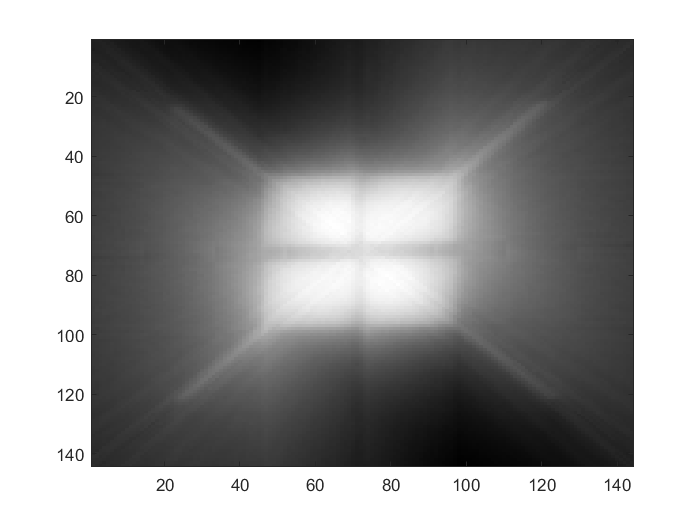

N = 180

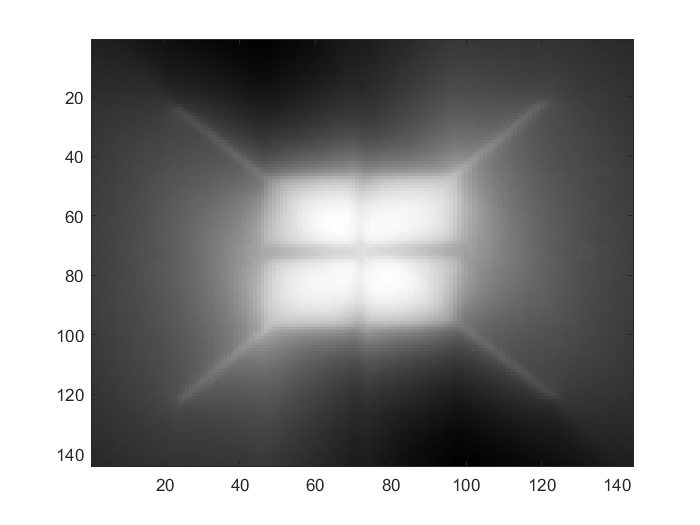

Ns = [6, 12, 30, 60, 180];
thetas = 0:179;
for N = Ns
    figure(N)
    N
    idx = 1:ceil(size(g,1)/N):size(g,1);
    
    back_proj = back_projection(g, thetas(idx), idx);
    
    imagesc(back_proj * pi / (2*N)); colormap gray
    
end

### *PART B: * Filtered Back Projection (FBP) 

*"B1. Draw a flow chart to illustrate how to compute the filtered back projection from the sinogram data. List the relevant equations and explain how they are related to each other." *

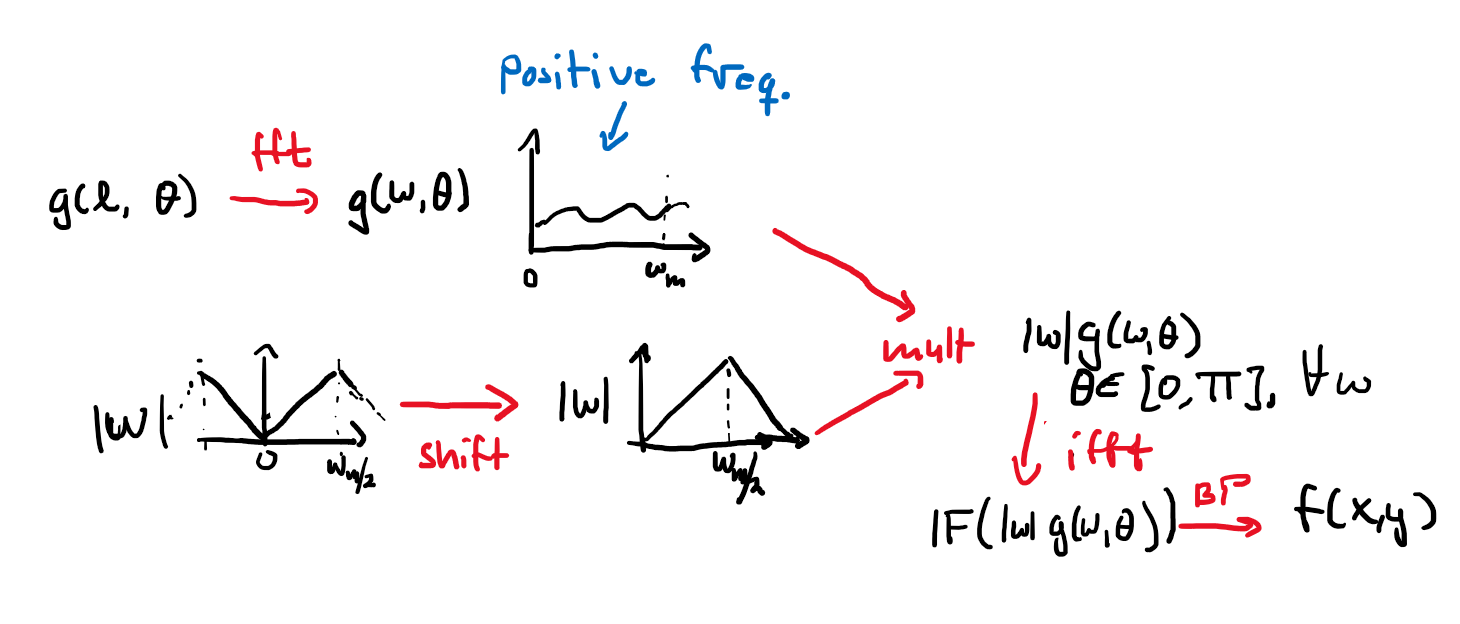

g(w, $\theta$) Radon transformed sinogram, f(x, y) the reconstructed image and |w| the filter. 

In order to filter the sinogram data, we first create a filter and then apply it to the Radon space sinogram. By inversely transforming it back we can then apply normal backprojection in order to reconstruct the filtered data.

The relevant equation can be seen below:

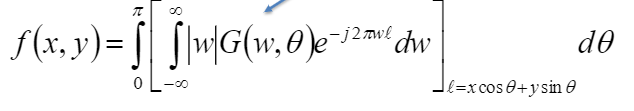

where $G\left(\omega ,\theta \right)\;$is the Radon transformed sinogram and |w| is the windowed filter. In this section we create a ramp filter for B2 and in B3 we apply a Hamming window to it. These procedures are described in the relevant subsections.

*"B2. Compute and plot the filtered back projection, with N= 6, 12, 30, 60 and 180, where N is the number of back projections. Multiply the resultant image by the factor of where N is the number of projections. Compare and comment on the results based on different values of N. (Question: Which value of N should we use?) "*

see below

*"B3. Repeat B2 with a Hamming window included in the filtering process. Comment on the results as compared to those in Part B2." *

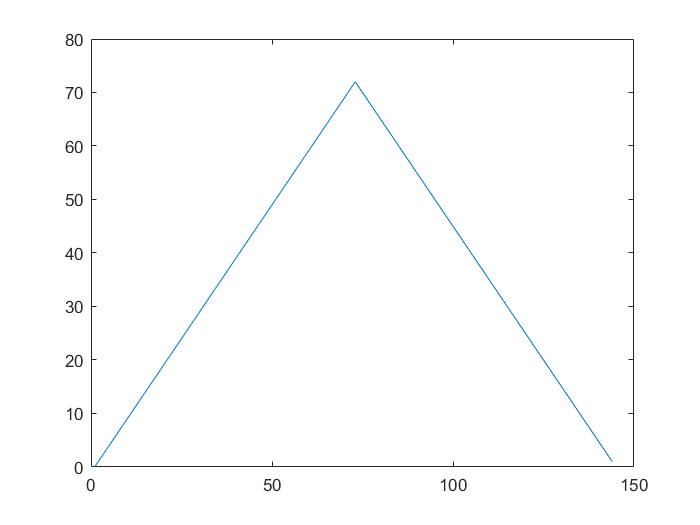

% Ramp filter - must ensure it exists in the positive frequency spectrum 
[gl, ~] = size(g); % Get size of l component of sinogram
mid = floor(gl / 2);    % Set the midpoint

% determine if the midpoint needs to be offset
if mod(gl, 2) == 0
    ramp = [0:mid, mid-1:-1:1];
else
    ramp = [0:mid, mid-1:-1:0];
end

plot(ramp)

N = 6

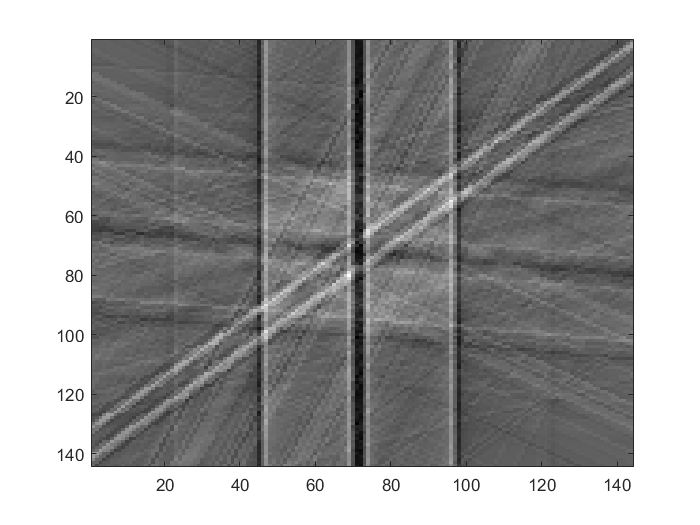

N = 12

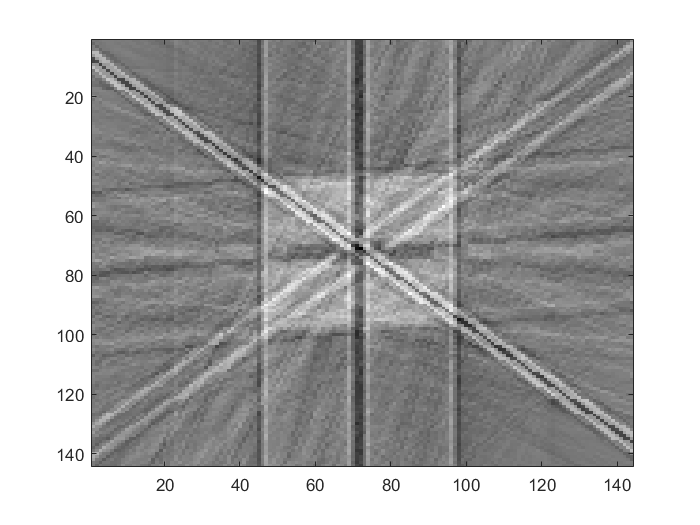

N = 30

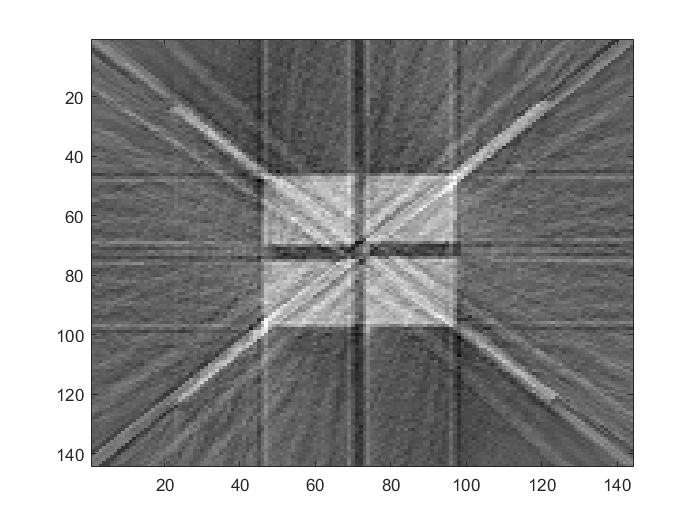

N = 60

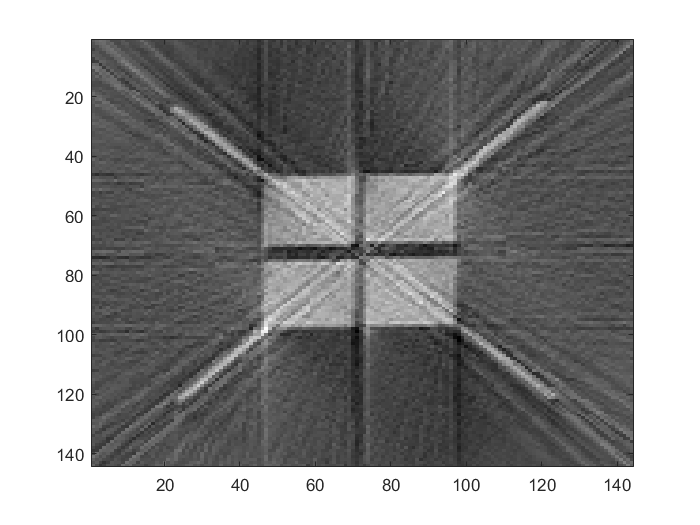

N = 180

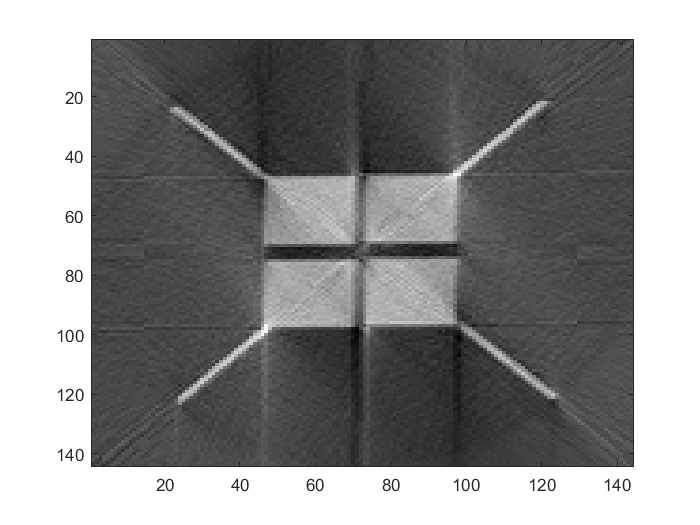


% B2 - Ramp filter
Ns = [6, 12, 30, 60, 180];
thetas = 0:179;
for N = Ns
    figure(N)
    N
    idx = 1:ceil(size(g,1)/N):size(g,1);
    
    back_proj = filtered_back_projection(g, thetas(idx), idx, 'ramp');
    
    imagesc(back_proj * pi / (2*N)); colormap gray
    
end

The blurry effect has been successfully removed, though there is a lot of noise present in the image at N = 180

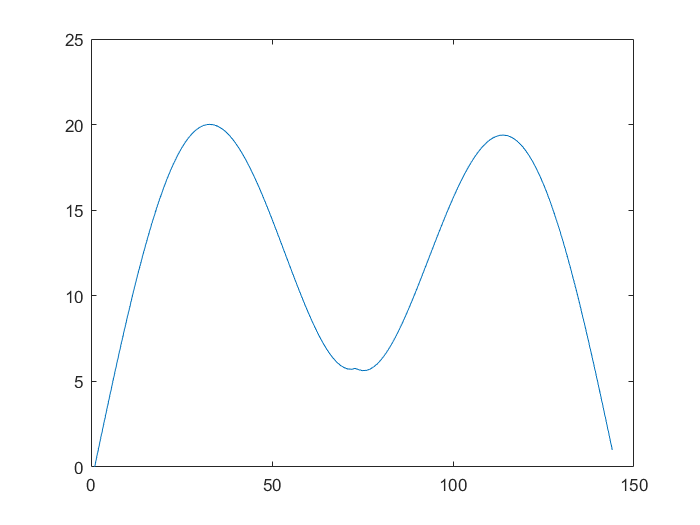

% B3 - Hamming filter

% The second filter we will use is a ramp windowed with a Hamming filter
% with a nonzero filter value at \rho = 0, so we reorder the hamming filter
% before using it to window the ramp.

h = hamming(size(g, 1));
Ham = [h(mid:gl); h(1:mid-1)].*ramp';
plot(Ham)

N = 6

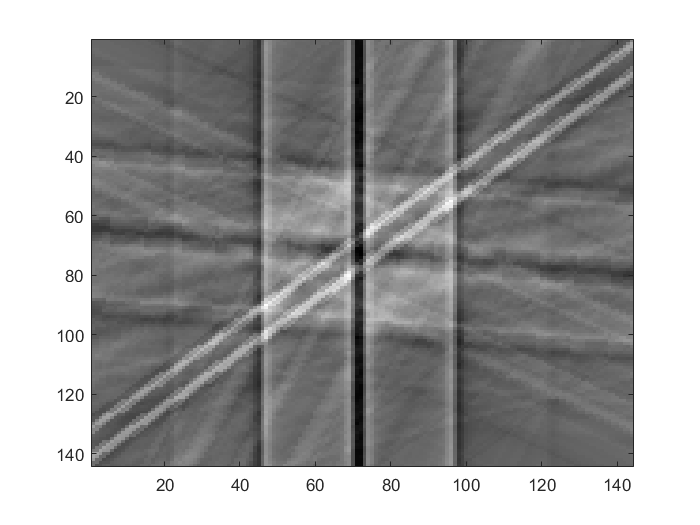

N = 12

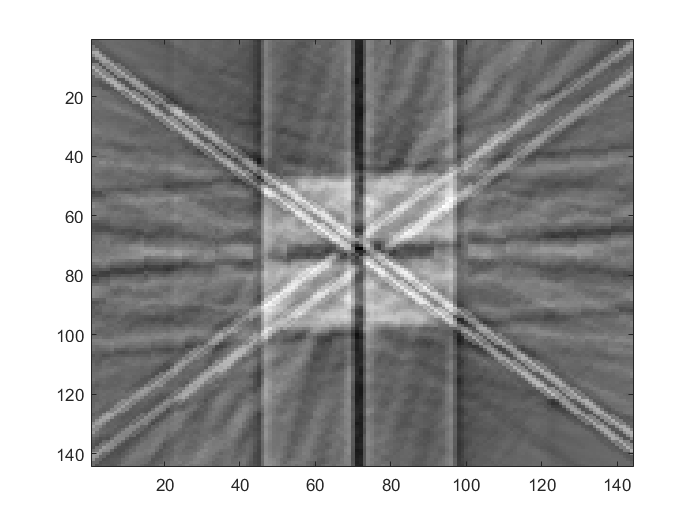

N = 30

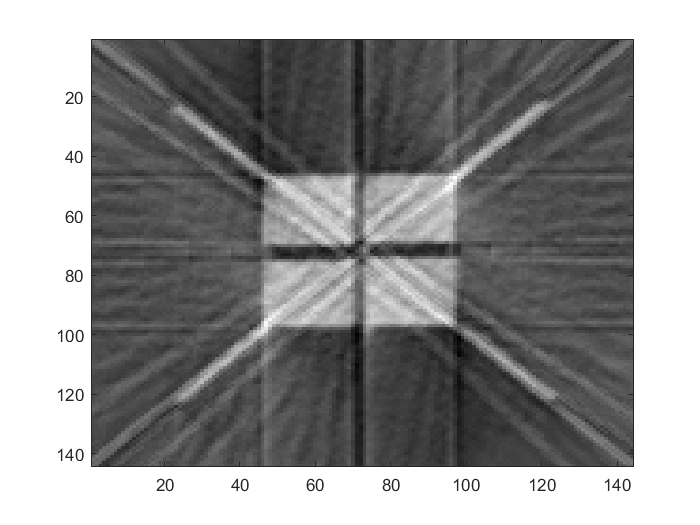

N = 60

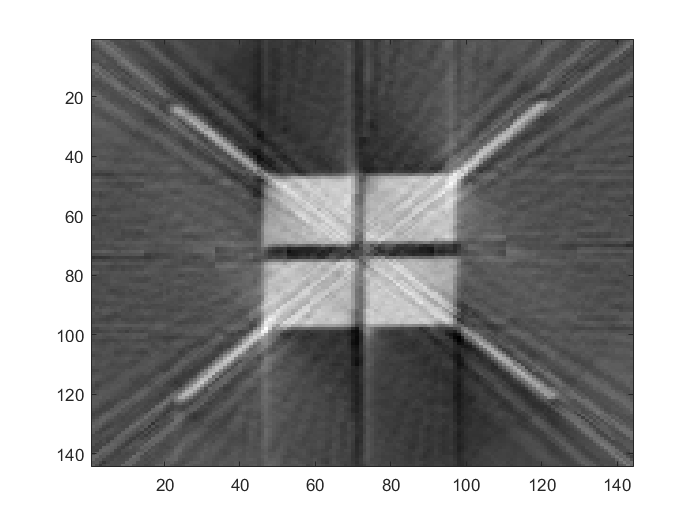

N = 180

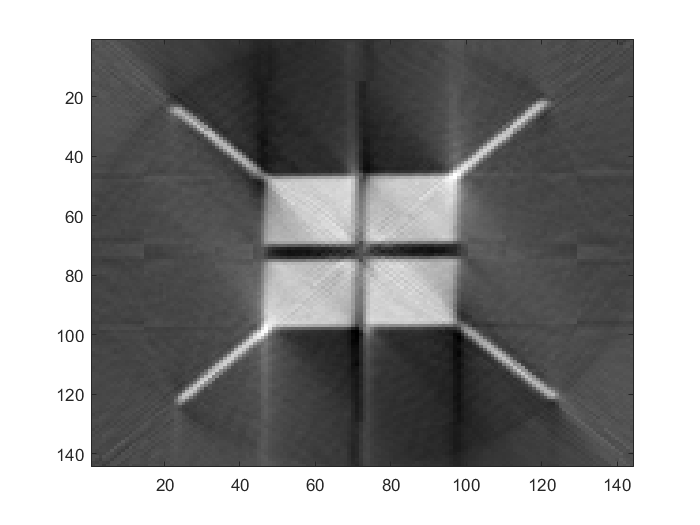

Ns = [6, 12, 30, 60, 180];
thetas = 0:179;
for N = Ns
    figure(N)
    N
    idx = 1:ceil(size(g,1)/N):size(g,1);
    
    back_proj = filtered_back_projection(g, thetas(idx), idx, 'hamming');
    
    imagesc(back_proj * pi / (2*N)); colormap gray
    
end

The result is definitely smoother than the non-windowed ramp function.

### PART C. Convolution Back Projection (CBP) 

*"C1. Explain the differences between filtered back projection and convolution back projection."*

Instead of writing it like

,

we rewrite it as 

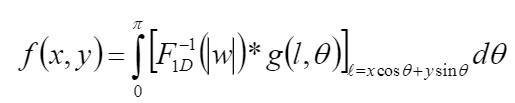

and thus get this 'convolution' between the ifft of |w| and g(l,$\theta$).  For infinite signals, this is of course the same but for finite siganls they differ. While the FBP attenuates smaller signals thus creating more contrast, the convolutional operator is known to be used for blurring, which ultimately should result in CBP having less contrast but smoother transitions. 

*"C2. Implement the convolution back projection algorithm with a Hamming window. Comment on the results as compared to those in Part B3." *

N = 6

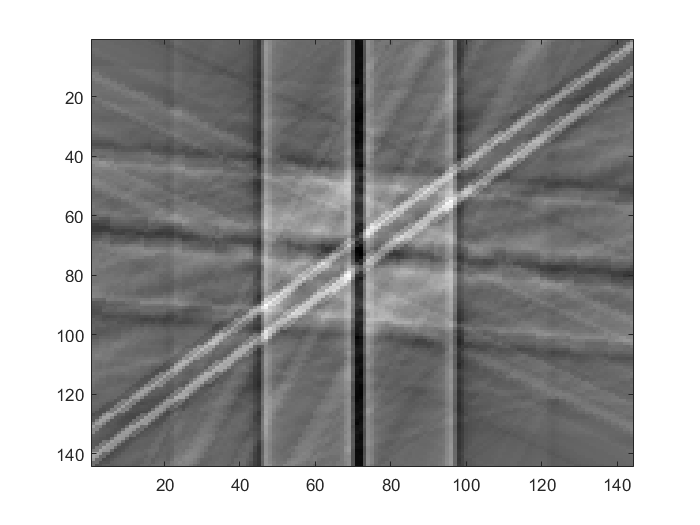

N = 12

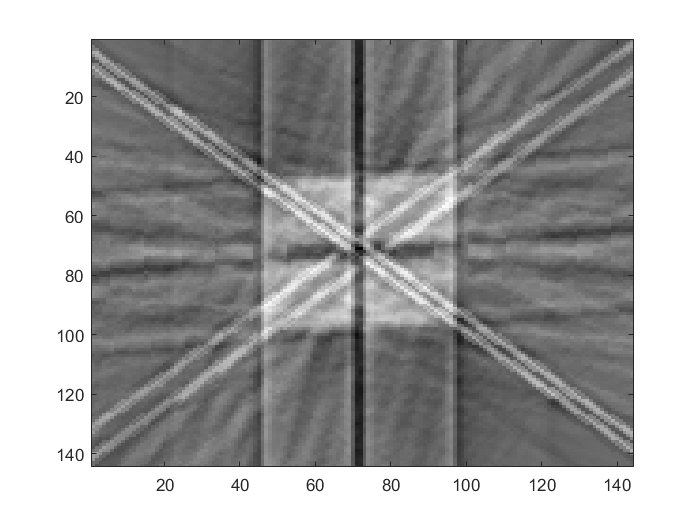

N = 30

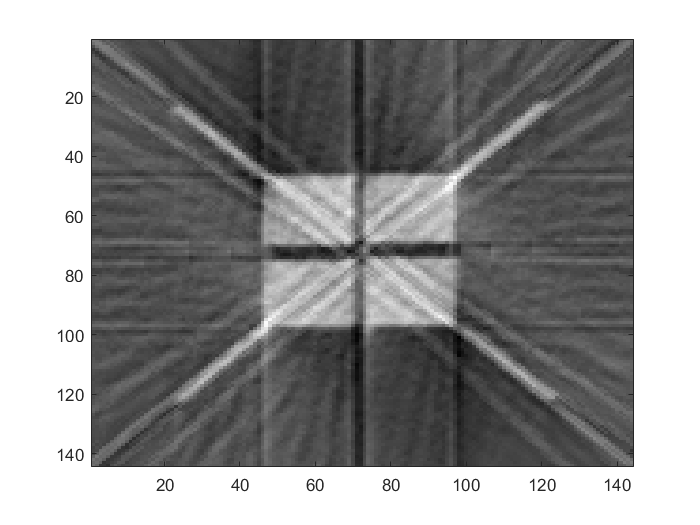

N = 60

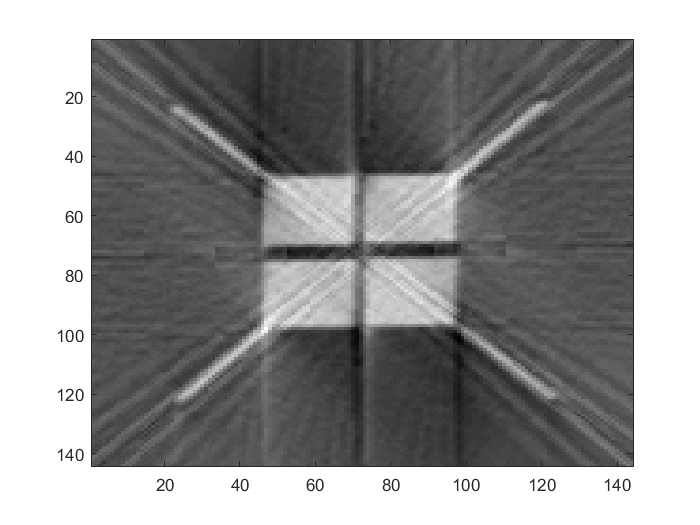

N = 180

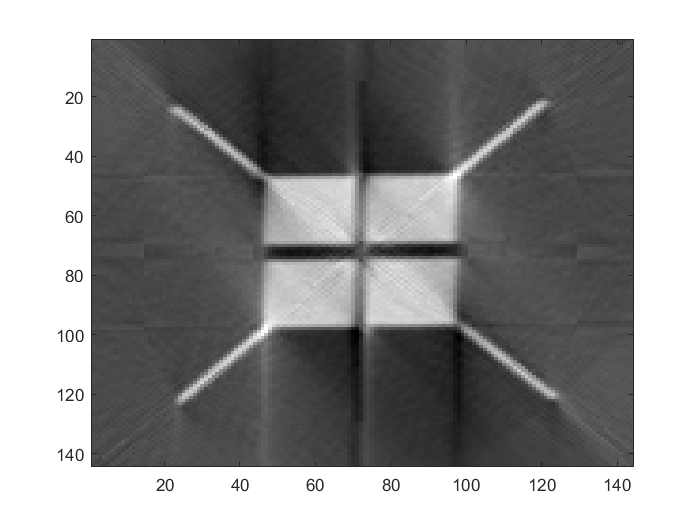

Ns = [6, 12, 30, 60, 180];
thetas = 0:179;
for N = Ns
    figure(N)
    N
    idx = 1:ceil(size(g,1)/N):size(g,1);
    
    back_proj = conv_back_projection(g, thetas(idx), idx, 'hamming');
    
    imagesc(back_proj * pi / (2*N)); colormap gray
    
end

*"C3. Compare and comment on the advantages and disadvantages of using FBP versus CBP."* 

As mentioned above, we have less contrast with the middle for FBP having more brighness and clearer borders to the background. The CBP is though much more smoother. 

### D. Fan-Beam Projections 

*"D1. What is fan-beam projection and fan-beam reconstruction? How many different geometries are there for fan-beam projection? Describe each of these." *

Basically we have 3 different geometries to work with. For this 'beam'-ing we instead of having parallel beams, multiple beams comes from one and the same place (S in images). Here we can change two things; the angle between the beams, and the spacing between the detectors (depends on detector geometry). While of course this opens up for multiple possibilities we simply chose to limit ourselves to 3 different versions;  

1.

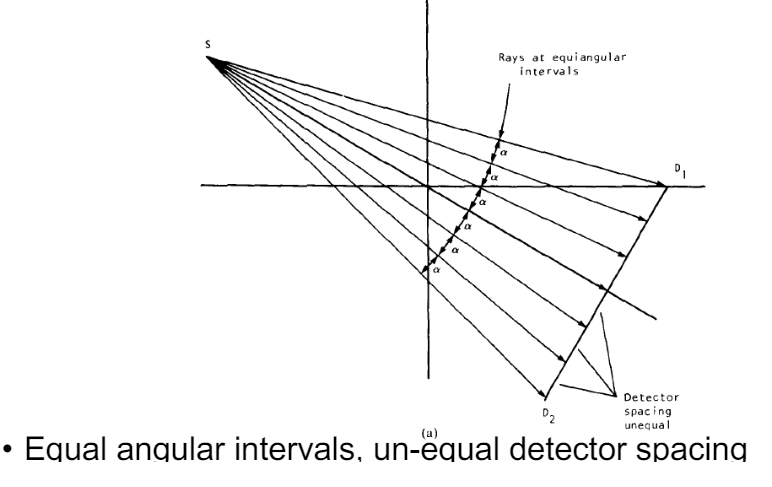

2. 

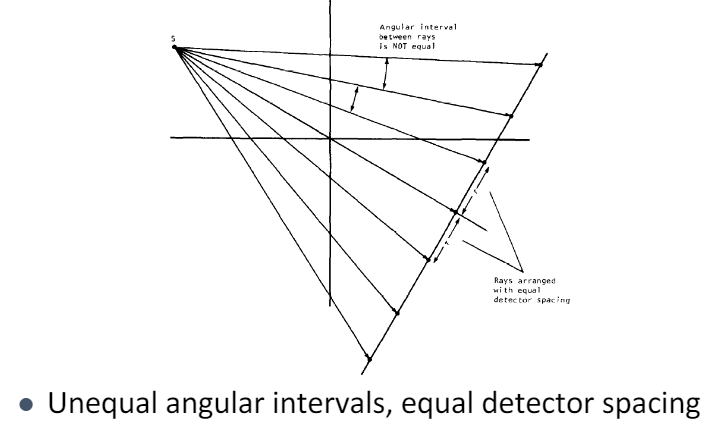

3. 

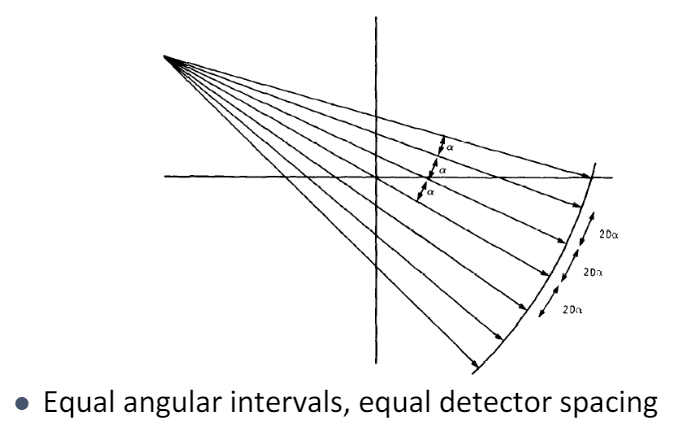

.

*"D2. Can we directly apply the implemented algorithm(s) in part B and C to measurements from some of the fan-beam projection geometries described in D1? Explain why. "*

Yes, using the last geometry (equal angular, equal spacing) and carefully cirling around the body with a fixed angle (same as in geometry), then we can see it as a parallel beams. I.e. 

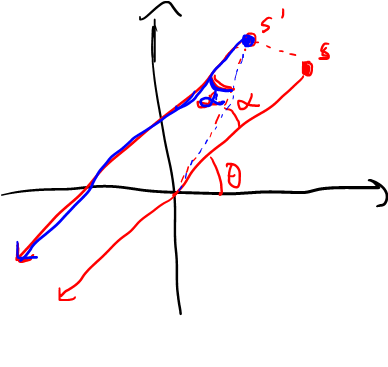

where s and s' are two different beam orientation position around the patient (origo as center). Here only one beam from each positon is shown but equally we can derive similar expressions for other beams (although with multiples of $\alpha^{\prime } s$).  

### E. Real CT-images 

*"You also get two additional filed containing sinograms. With load('data.mat') also the sinograms g2 and g3 are loaded. With size(g2) in MATLAB the size of the matrix is found, it should be 1095 180. The third sinogram g3 should have size 895 360. The sinogram g2 was formed based on multiple parallel beam projections of an object from 180 different directions: 0 to 179 degrees with a step size of 1 degree. The sinogram g3 was formed based on multiple parallel beam projections of an object from 360 different directions: 0 to 179.5 degrees with a step size of 0.5 degrees. "*

*"E1. Reconstruct these two images using the three reconstruction methods that you have implemented. You can do this for N = 180, and N = 360, respectively otherwise use the settings for each algorithm that resultet in the best reconstruction. "*

set(groot, 'DefaultTextInterpreter', 'none')

thetas_g2 = 0:179;        idx_g2 = 1:length(thetas_g2);
thetas_g3 = 0:.5:179.5;   idx_g3 = 1:length(thetas_g3);

bp_fvec = {@back_projection, @filtered_back_projection, @conv_back_projection};
h = figure(1);
disp("g2 reconstruction, using " )

g2 reconstruction, using 


for i = 1:3
    fun = bp_fvec{i};
    tic
    back_proj = fun(g2, thetas_g2, idx_g2);
    toc
    subplot(1,3,i)
    imagesc(back_proj * pi / (2*180)); colormap gray
    title(char(fun))
end

Elapsed time is 9.996796 seconds.


Elapsed time is 9.939882 seconds.


Elapsed time is 9.954333 seconds.


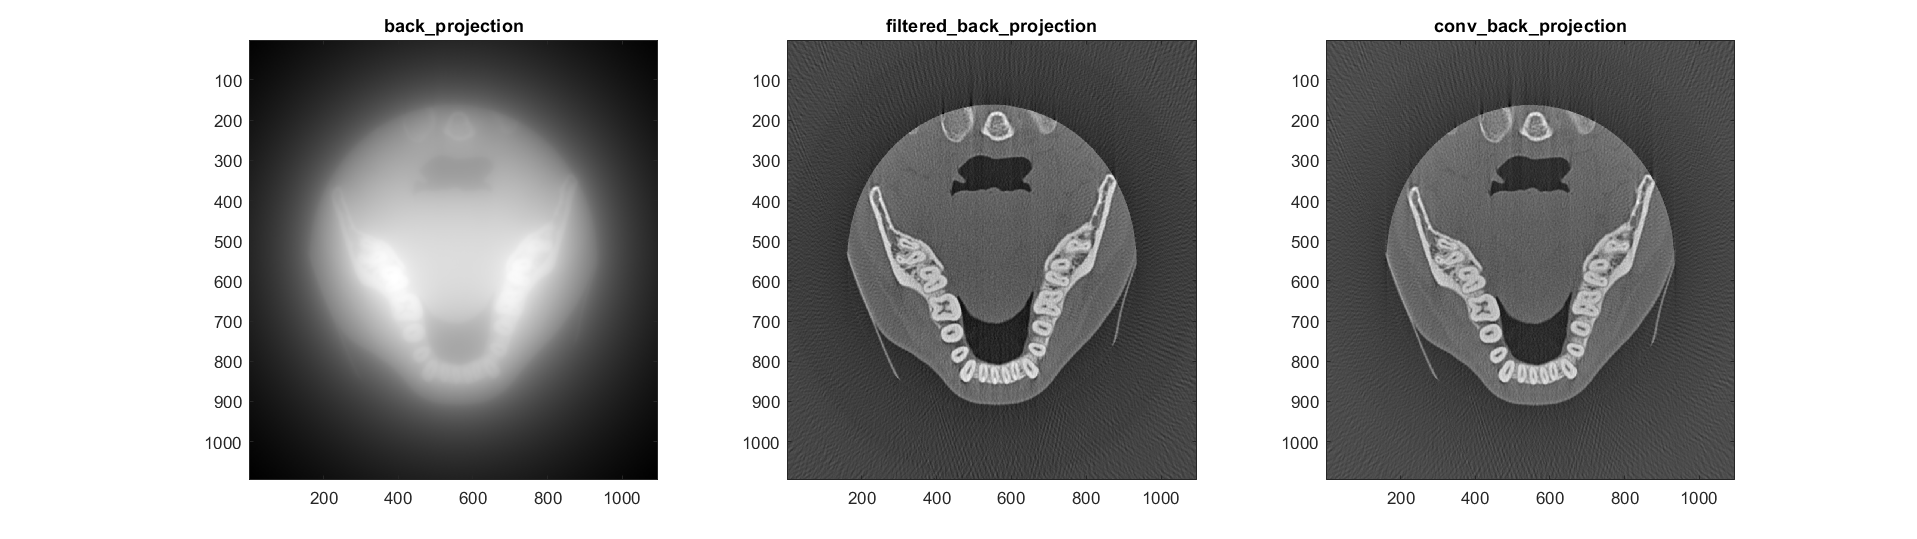

set(h,'Units','normalized','Position',[0 0 2 1]);

h = figure(2);
disp("g3 reconstruction, using " )

g3 reconstruction, using 


for i = 1:3
    fun = bp_fvec{i};
    tic
    back_proj = fun(g3, thetas_g3, idx_g3);
    toc
    subplot(1,3,i)
    imagesc(back_proj * pi / (2*180)); colormap gray
    title(char(fun))
end

Elapsed time is 12.471518 seconds.


Elapsed time is 12.560835 seconds.


Elapsed time is 12.517640 seconds.


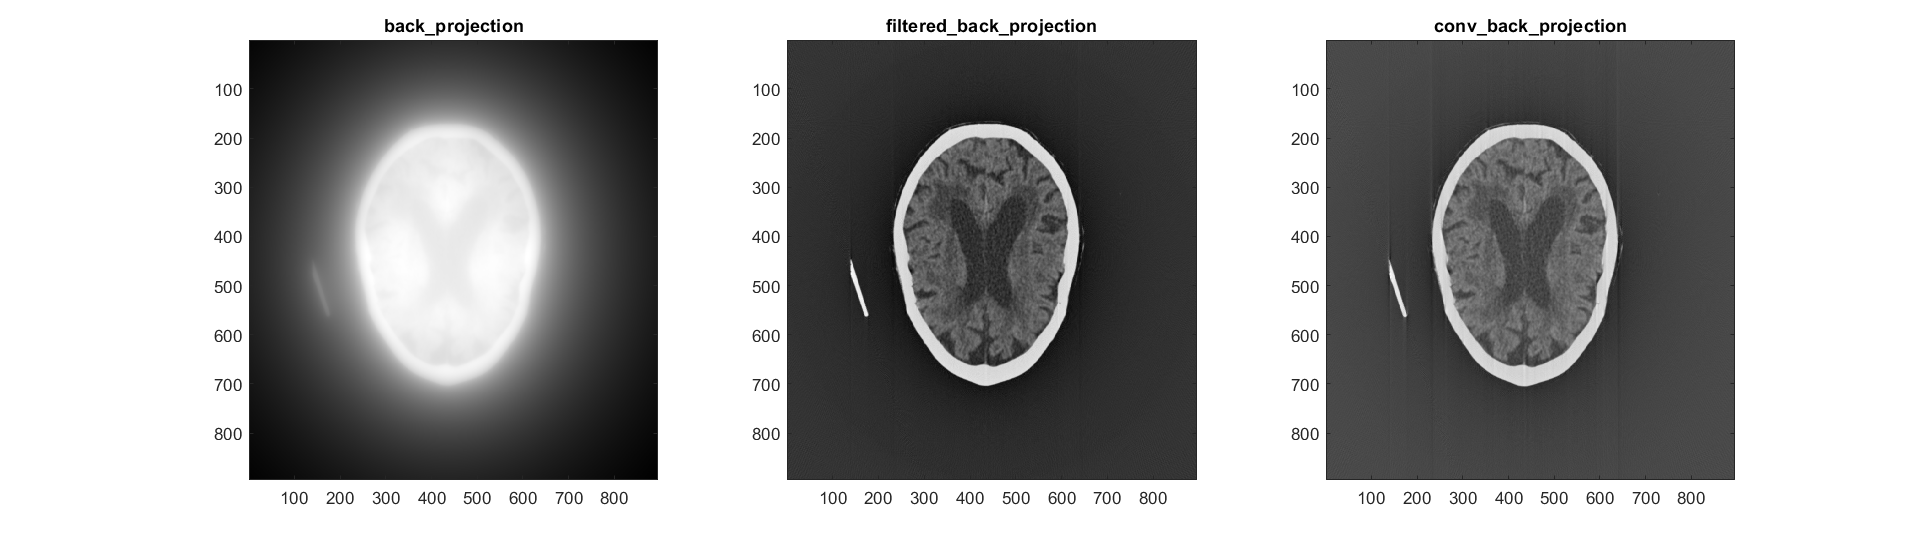

set(h,'Units','normalized','Position',[0 0 2 1]);

*"E2. Compare these images and comment on similarities or differences in the reconstruction results. What do you need to do to improve the reconstruction even further?"* 

The filtered image looks clearer than the convoluted one, almost if the convolved image were more noisy. A potential fix to this is to tune the windowing function to filter out that specific noise. The ordinary back projection algorithm is very bright which is due to not being filtered. Each point then contibutes to added brighness. 

Seems like one common new technology to improve image quality is using machine learning. For instance [this paper](https://www.researchgate.net/publication/328633508_Improving_Tomographic_Reconstruction_from_Limited_Data_Using_Mixed-Scale_Dense_Convolutional_Neural_Networks). This of course requires more data to train on. 